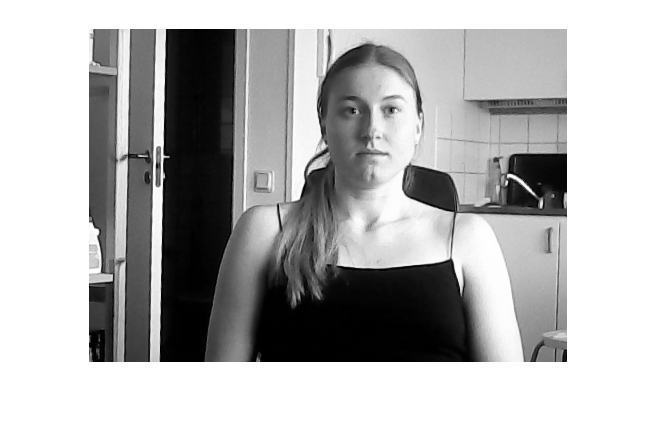

left = imread("leftimg9.png");
right = imread("rightimg9.png");
live = imread("liveimg9.png");
load("stereocalib.mat")
load("leftcalibsingle.mat")
load("rightcalibsingle.mat")
%fix images

% imshow(left)
% imshow(right)
[left,right] = rectifyStereoImages(left,right,stereoParams);
imshow(left)

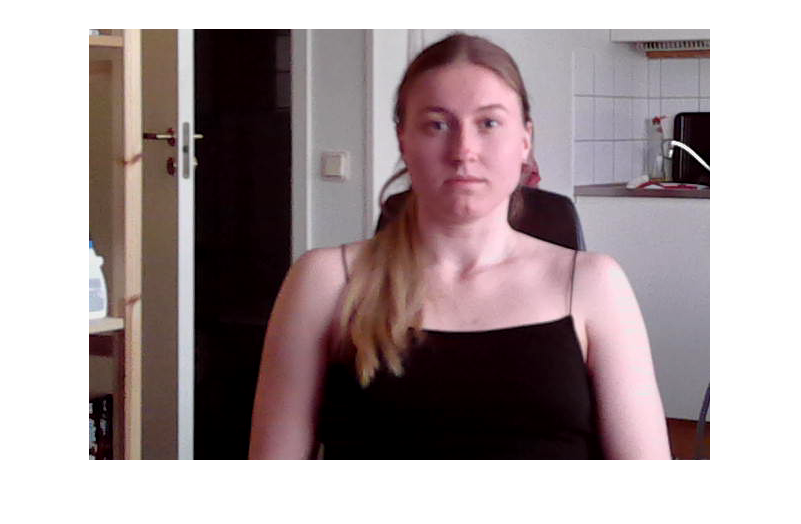

%imshow(right)
w = 620; 
h = 430;
xstart = 510;
ystart = 405;
%rect = rectangle('Position',);
croplive = imcrop(live,[xstart ystart w h]);
imshow(croplive)

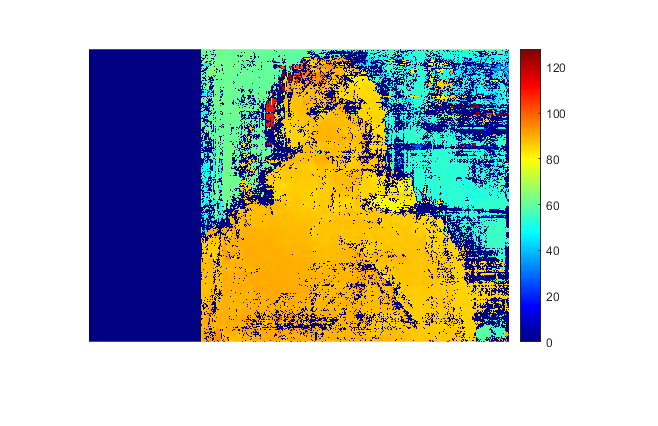

%636 
disparityRange = [0 128];
uniq = 7;
dispMap1 = disparitySGM(left,right, "DisparityRange", disparityRange, 'UniquenessThreshold',uniq);

figure;
imshow(dispMap1, disparityRange)
colormap jet
colorbar

threshhold = 70;
% 
mask = dispMap1;

disp('Not a number removed')

Not a number removed


mask(mask ~= mask) = 0;
disp('Medfilt')

Medfilt


mask = medfilt2(mask,[5 5]);
disp('Gauss')

Gauss


mask = imgaussfilt(mask,5);
disp('Threshold applied')

Threshold applied


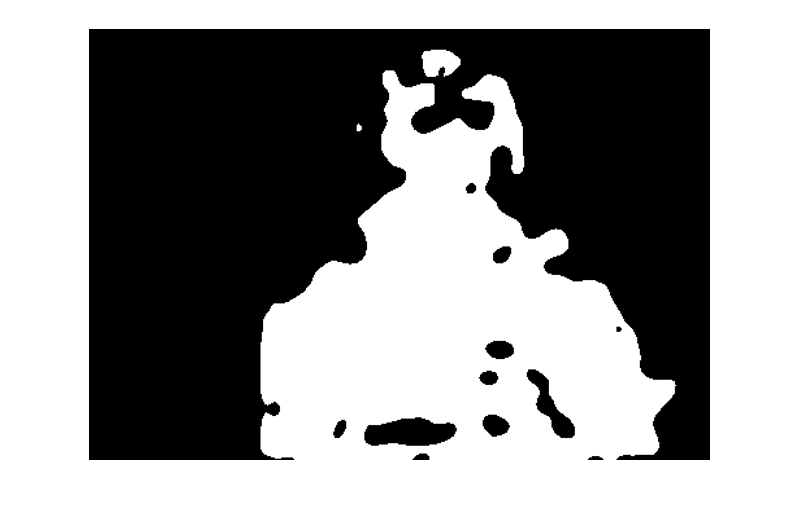

mask(mask < threshhold) = 0;
mask(mask >= threshhold) = 1;
mask = imresize(mask,[(h + 1) (w + 1)]);
imshow(mask)

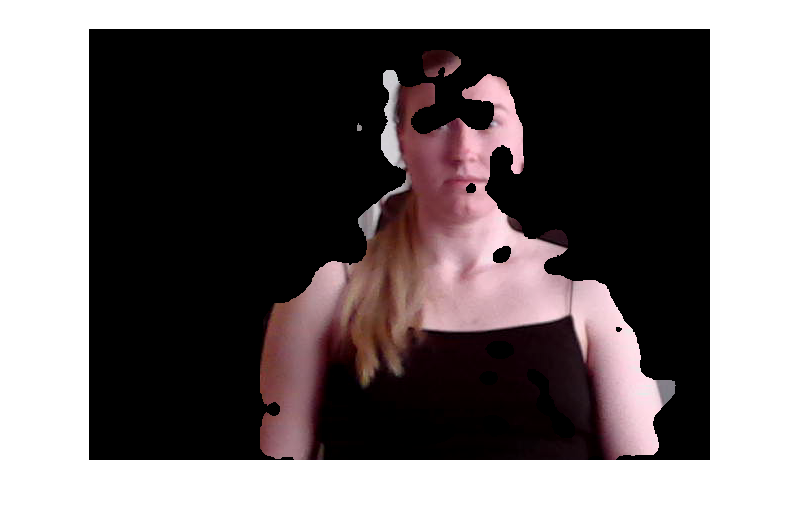


for i = 1:3
    croplive(:,:,i) = immultiply(uint8(mask),croplive(:,:,i));
end

imshow(croplive)